# Praktikum 2: Aufgabe 1

% f: die zu minimierende Funktion f(x)
% df: Ableitung der Funktion, f'(x)
[f, df] = createFuncsA1();

## Plotten der Funktion

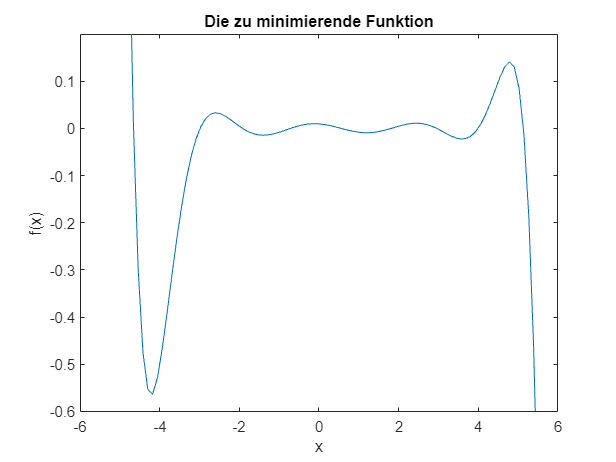

xx = linspace(-6, 6);
plot(xx, f(xx));
ylim([-0.6, 0.2]);
xlabel('x'), ylabel('f(x)'), title('Die zu minimierende Funktion');

## Gradientenabstieg


% Find the best hyper parameters for a gradient descent algorithm using RMSProp
% beta: the parameter beta
% eta: the parameter eta
% iter: the number of iterations
% x0: the starting point
% track: the track of the algorithm
% epsilon: the parameter epsilon



% Anfangswerte
x0 = 4.7;   % Anfangspunkt, nicht ändern!

% Hyperparameter
iter = 1000;
beta = 0.9;
eta = 0.1;
gamma = 0.995;

% RMSProp
[w, track] = gaRmsProp(df, eta, x0, iter, beta);
w

w = 3.5433

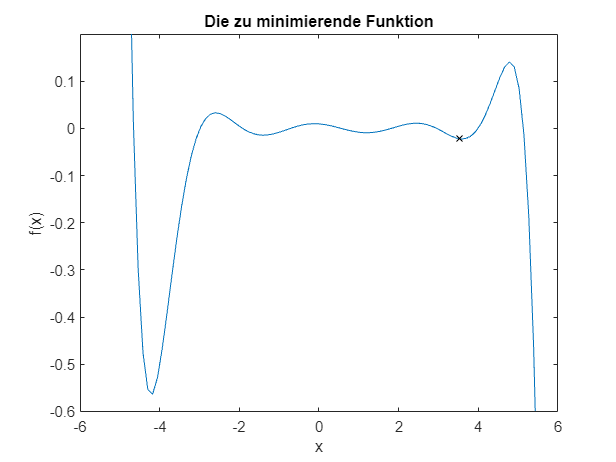


% for ii = 1:iter
%     s(ii+1) = s(ii) * beta + (1-beta) * df(x0(ii)) * df(x0(ii));
%     step_size(ii+1) = eta/sqrt(s(ii+1) + epsilon);
%     x0(ii+1) = x0(ii) - step_size(ii+1) * df(x0(ii));
% end
% track(end+1) = x0(end);

hold on
plot(w, f(w), '--kx')
hold off

[w, track] = gaNAG(df, eta, x0, iter, gamma);
w

w = -4.2225

gamma = 1;

beta = 0.9;

[w, track] = gaRmsNAG(df, eta, x0, iter, gamma, beta);
track

track =     4.3838    3.8160    3.3252    2.8938    2.4647    1.9894    1.4800    0.9966    0.5648    0.1643   -0.2545   -0.7448   -1.2739   -1.6880   -1.9482   -2.0655   -2.0455   -1.8981   -1.6694   -1.4315   -1.2345   -1.0999   -1.0353   -1.0422   -1.1157   -1.2379   -1.3713   -1.4717   -1.5145   -1.5029   -1.4590   -1.4098   -1.3751   -1.3631   -1.3709   -1.3880   -1.4028   -1.4091   -1.4076   -1.4029   -1.3994   -1.3985   -1.3993   -1.4002   -1.4005   -1.4004   -1.4002   -1.4002   -1.4002   -1.4002


w

w = -1.3719